% AAE 532 HW 9 Problem 2
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps9';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
mercury = planet_consts.mercury;  % structure of mercury 
venus = planet_consts.venus;  % structure of venus
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)

% Original Transfer Orbit
mu_sun = sun.gp;
mu_earth = earth.gp;
mu_venus = venus.gp;
mu_mercury = mercury.gp;
r_p0 = 0.5 * earth.smao

r_p0 = 74798949

r_a0 = earth.smao

r_a0 = 149597898

a_0 = 0.5*(r_p0 + r_a0)

a_0 = 1.1220e+08

e_0 = (r_a0 - r_p0) / (r_a0 + r_p0)

e_0 = 0.3333

p_0 = a_0 * (1 - e_0^2)

p_0 = 99731932

r_venus = venus.smao

r_venus = 108207284

TA_venus = acos_dbval(1 / e_0 * (p_0 / r_venus - 1), "deg")

TA_venus =   103.5902 -103.5902


TA_venus = TA_venus(TA_venus < 0)

TA_venus = -103.5902

E_venus = T2E_anomaly(e_0, TA_venus, "deg")

E_venus = -83.8739

MM_0 = sqrt(a_0^3 / mu_sun);
TOF_venus = pi*MM_0 - MM_0 * (deg2rad(-E_venus) - e_0 * sind(-E_venus))

TOF_venus = 6.5544e+06

TOF_venus_days = TOF_venus / 60 / 60 / 24 

TOF_venus_days = 75.8616

% (b)

% What is the actual venus radii of the encounter
h_venus = 2990;
r_p_fb = h_venus + venus.mer

r_p_fb = 9.0419e+03

% Find the pre-encounter conditions 
v_venus = sqrt(mu_sun / r_venus)

v_venus = 35.0209

v_minus = vis_viva(r_venus, a_0, mu_sun)

v_minus = 35.6384

FPA_minus = -acosd(sqrt(mu_sun*p_0) / r_venus / v_minus)

FPA_minus = -19.3683


% Find the v-infinity 
v_inf_venus = sqrt(v_venus^2 + v_minus^2 - 2*v_venus*v_minus*cosd(FPA_minus))

v_inf_venus = 11.9017


% Find hyperbola characteristics 
En_fb = v_inf_venus^2 / 2 

En_fb = 70.8248

a_fb = -mu_venus / 2 / En_fb

a_fb = -2.2934e+03

e_fb = 1 - r_p_fb / a_fb

e_fb = 4.9426

delta = 2*asin_dbval(1 / e_fb, "deg")

delta =    23.3457  336.6543


delta = delta(1) 

delta = 23.3457

% New orbit
eta = asind(v_minus / v_inf_venus * sind(-FPA_minus)) - abs(delta)

eta = 59.9015

v_plus = sqrt(v_inf_venus^2 + v_venus^2 - 2*v_inf_venus*v_venus*cosd(eta))

v_plus = 30.8231

FPA_plus = -asind(v_inf_venus / v_plus * sind(eta))

FPA_plus = -19.5156

% True anomaly
r_plus = r_venus;
temp = r_plus * v_plus^2 / mu_sun;
TA_plus = atan_dbval( temp*sind(FPA_plus)*cosd(FPA_plus) / ( temp*cosd(FPA_plus)^2 - 1 ), "deg")

TA_plus =    38.0341 -141.9659


TA_plus = TA_plus(TA_plus == min(TA_plus))

TA_plus = -141.9659

h_plus = r_plus*v_plus*cosd(FPA_plus)

h_plus = 3.1437e+09

p_plus = h_plus^2 / mu_sun

p_plus = 7.4467e+07

e_plus = 1/cosd(TA_plus) * (p_plus/r_plus - 1)

e_plus = 0.3959

a_plus = p_plus / (1 - e_plus^2)

a_plus = 8.8306e+07

r_p_plus = a_plus * (1 - e_plus)

r_p_plus = 5.3348e+07

r_a_plus = a_plus * (1 + e_plus)

r_a_plus = 1.2326e+08

IP_plus = 2*pi * sqrt(a_plus^3 / mu_sun)

IP_plus = 1.4312e+07

IP_plus_years = IP_plus / 60 / 60 / 24 

IP_plus_years = 165.6527

Domega = TA_venus - TA_plus

Domega = 38.3758

r_mercury = mercury.smao;
TA_mercury = acosd(1/e_plus * (p_plus/r_mercury - 1))

TA_mercury = 43.7576

Dv_eq = 2*v_inf_venus*sind(delta / 2)

Dv_eq = 4.8160

alpha = (abs(FPA_plus)-abs(FPA_minus)) + (180 - delta)/2 + (180 - eta - abs(FPA_plus))

alpha = 179.0573

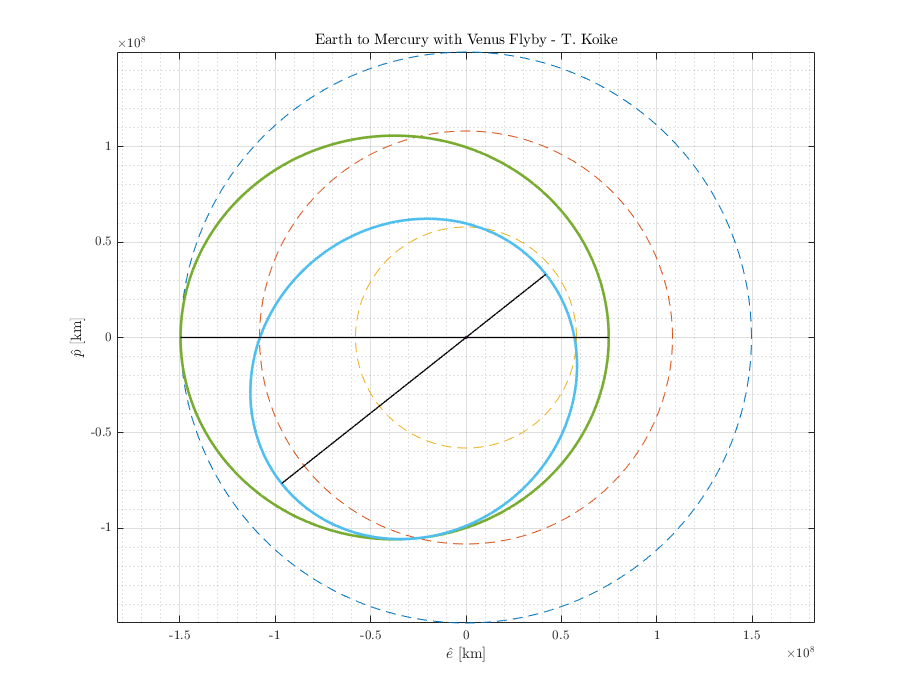

% (d)

% plotting
angles = 0:0.001:2*pi;

% Earth orbit
Xearth = earth.smao * cos(angles); Yearth = earth.smao * sin(angles);

% Venus orbit
Xvenus = venus.smao * cos(angles); Yvenus = venus.smao * sin(angles);

% Mercury orbit
Xmercury = mercury.smao * cos(angles); Ymercury = mercury.smao * sin(angles);

% Sun
Xsun = sun.mer * cos(angles); Ysun = sun.mer * sin(angles);

% Earth to Venus  
angles = 0:0.1:360;
R_E2V = p_0 ./ (1 + e_0*cosd(angles)); X_E2V = R_E2V.*cosd(angles); Y_E2V = R_E2V.*sind(angles);

% Venus to Mercury
R_V2M = p_plus ./ (1 + e_plus*cosd(angles - Domega));
X_V2M = R_V2M .* cosd(angles); Y_V2M = R_V2M .* sind(angles);


fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
    plot(Xearth,Yearth, '--')
    hold on; grid on; grid minor; box on; axis equal; 
    plot(Xvenus, Yvenus, '--')
    plot(Xmercury, Ymercury, '--')
    plot(Xsun, Ysun)
    plot(X_E2V, Y_E2V, "LineWidth", 2)
    plot(X_V2M, Y_V2M, "LineWidth", 2)
    
    plot([-r_a0, r_p0], [0, 0], '-k', 'LineWidth', 1)
    
    r_a_plus_vec = r_a_plus * [-cosd(Domega), -sind(Domega)];
    r_p_plus_vec = r_p_plus * [cosd(Domega), sind(Domega)];
    temp = vertcat(r_a_plus_vec, r_p_plus_vec);
    plot(temp(:, 1), temp(:, 2), '-k', "LineWidth", 1)
    
    hold off
    title('Earth to Mercury with Venus Flyby - T. Koike')
    xlabel('$\hat{e}$ [km]')
    ylabel('$\hat{p}$ [km]')
saveas(fig, fullfile(fdir, "p2_earth2mercury.png"))